# Frequency analysis of a one-dimensional data set (c-e)

% Assignment 2. Part (c) - (e)
% Names: Timur Holikov, Lea Ebenschweiger

### (c) The power spectral density:

#### 
$$S_{\mathrm{yy}} \left(k\right)=\frac{1}{n^2 }{\;\left|\sum_{j=0}^{n-1} y_j \;\exp \left(i\;\frac{2\pi \mathrm{kj}}{n}\right)\;\right|}^2 ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;k=0,\ldotp \ldotp \ldotp ,n-1\ldotp$$


[y, SR] = audioread('single_tone.ogg');
y_L = y(:,1); %import left channel
n = length(y_L);

% Find the next power of 2
n_ext = 2^nextpow2(n);

% Extend the signal with zeros
y_ext = [y_L; zeros(n_ext-n, 1)];


FFT:

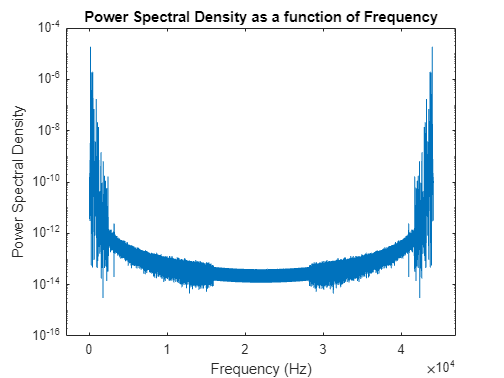

Y_FFT = fft(y_ext);

%% (c)
S = 1/(n_ext^2)*(abs(Y_FFT)).^2;

f = (1:n_ext)*SR/n_ext; % frequencies in Hz

figure
% plot(f, S)
semilogy(f, S)
xlabel('Frequency (Hz)')
%xlim([0 SR/2])  % Limit the x-axis to [0, Nyquist frequency]
xlim([-0.3*10^(4) 4.7*10^4])
ylabel('Power Spectral Density')
title('Power Spectral Density as a function of Frequency')


% grid on


### (d): 

% Find the fundamental frequency
[~, idx] = max(S);
fundamental_freq = f(idx);
disp(fundamental_freq);

  147.3679



The fundamental frequency correponds to the note D3. 

### (e): What would be the Fourier representation of a perfect tone? How can the frequency spectrum be used to approximate the test file using a limited number of frequencies?

-  The perfect tone is a sine wave of a single frequency, and the Fourier transform decomposes a function into its component frequencies. So the Fourier representation of a perfect tone will be just a single peak at the frequency of the tone.

- The frequency spectrum can be used to approximate a test file using a limited number of frequencies by identifying the frequencies with the highest amplitudes in the spectrum. They correspond to the most “important”/"basic" frequencies of the signal (those that most affect its shape and characteristics. in the context of audio signals, these frequencies determine the pitch and timbre of the sound). By summing the sinusoids of these frequencies, one can obtain a signal that approximates/approaches the original one, although some information is inevitably lost in the process, which can result in changes to the sound.

% Consider only up to Nyquist frequency. Isn't that necessary, but allows
% to make a better approximation
nyquistIdx = SR/2;
S = S(1:nyquistIdx);
f = f(1:nyquistIdx);

% Identify top frequencies
[pks, locs] = findpeaks(S);
[~, sortIndex] = sort(pks, 'descend');
topFreqs = f(locs(sortIndex(1:6)));

% Generate signal
approxSignal = zeros(size(y_ext));
for freq = topFreqs
    approxSignal = approxSignal + sin(2*pi*freq*(0:length(y_ext)-1)/SR)';
end

% Normalize to [-1, 1]. Prevents ddistortion
approxSignal = approxSignal / max(abs(approxSignal));

audiowrite('approximation.ogg', approxSignal, SR);
